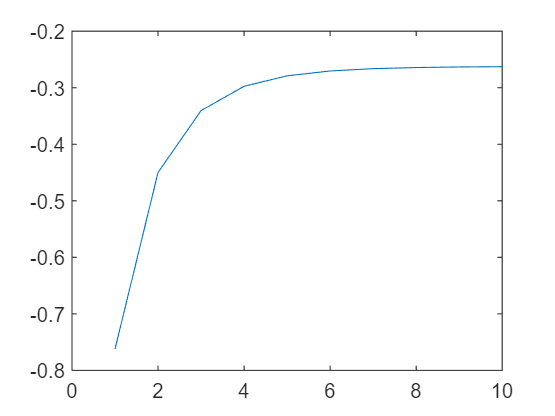

A = 0.32345;
B = -0.78743;
C = 0.56532;

double_result = (A + B) * C;

number_of_tested_precisions = 10;
list_of_results = [];

for j = 1:number_of_tested_precisions
    n_bits = j;
    a_prec = -1;
    b_prec = -1;
    c_prec = -1;
    
    for i = 1:n_bits
        if a_prec < A
            a_prec = a_prec + (1/2)^i;
        end
        if b_prec < B
            b_prec = b_prec + (1/2)^i;
        end
        if c_prec < C
            c_prec = c_prec + (1/2)^i;
        end
    end
    limited_precision_result = (a_prec + b_prec) * c_prec;
    result_for_given_precision = double_result - limited_precision_result;
    list_of_results = [list_of_results, result_for_given_precision];
end

plot(1:number_of_tested_precisions, list_of_results)

signed=1;
prec_i=1;
prec_f=8;
word = 1 + prec_i + prec_f; % whole word
A_fixed = fi(A,signed,word,prec_f);
B_fixed = fi(B,signed,word,prec_f);
C_fixed = fi(C,signed,word,prec_f);

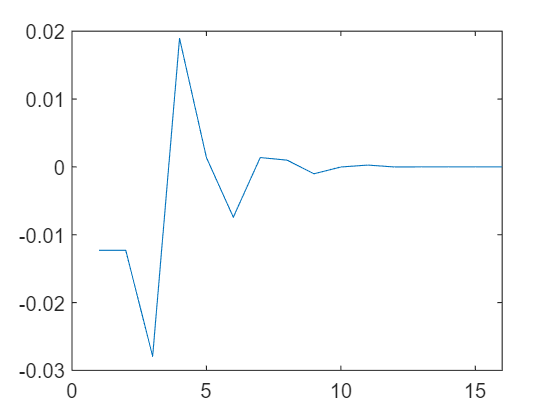

list_of_results = [];
list_of_results_abs = [];
n = 16;

for n_precision_bits = 1:n
    prec_f=n_precision_bits;
    word = 1 + prec_i + prec_f; % whole word
    A_fixed = fi(A,signed,word,prec_f);
    B_fixed = fi(B,signed,word,prec_f);
    C_fixed = fi(C,signed,word,prec_f);
    limited_precision_result = (A_fixed + B_fixed) * C_fixed;
    result_for_given_precision = double_result - double(limited_precision_result);
    list_of_results = [list_of_results, result_for_given_precision];
    list_of_results_abs = [list_of_results_abs, abs(result_for_given_precision)];
end

plot(1:n, list_of_results)

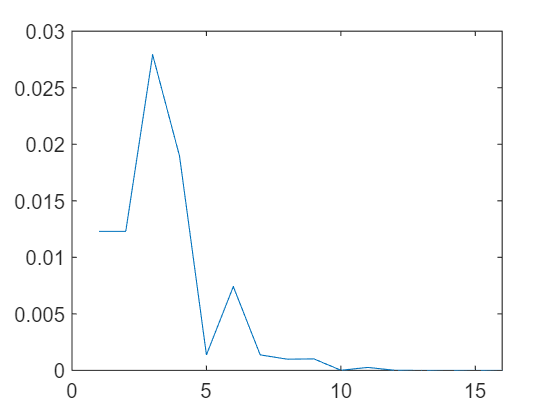

plot(1:n, list_of_results_abs)

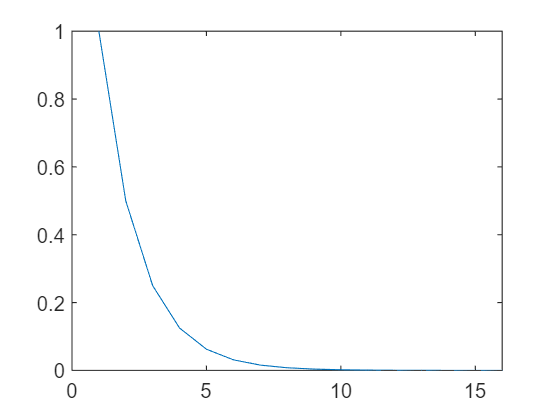

A = 2; B = 2;
double_result = A + B;
list_of_results = [];
list_of_results_abs = [];
n = 16;

signed=1;
prec_i=1;

for n_precision_bits = 1:n
    prec_f=n_precision_bits;
    word = 1 + prec_i + prec_f; % whole word
    A_fixed = fi(A,signed,word,prec_f);
    B_fixed = fi(B,signed,word,prec_f);
    limited_precision_result = (A_fixed + B_fixed);
    result_for_given_precision = double_result - double(limited_precision_result);
    list_of_results = [list_of_results, result_for_given_precision];
    list_of_results_abs = [list_of_results_abs, abs(result_for_given_precision)];
end

plot(1:n, list_of_results)

plot(1:n, list_of_results_abs)